**1.    Rauschunterdrückung durch Mittelung**

Es gibt zwei verschiedene Bildersätze mit jeweils 100 Aufnahmen von einem Pumpengehäuse (Bildrauschen1_#.png, Bildrauschen2_#.png). Die einzelnen Bilder sind leider stark verrauscht.

- Führen Sie im Matlab LiveScript eine Rauschunterdrückung durch, indem Sie die Bilder beider Serien jeweils mitteln! Innerhalb einer for-Schleife soll in jedem Schleifendurchlauf ein Bild der Serie eingelesen und in `uint16` gewandelt werden und diese Bilder aufzusummiert werden(`imadd).` Nutzen Sie die Matlab-Hilfe um sich über diese Funkttion zu informieren!

- Hierbei wird davon ausgegangen, dass das Rauschen dynamisch ist und der Erwartungswert des Rauschanteils gleich Null ist. Durch die Mittelung einer hinreichend großen Anzahl an Bildern kann das Rauschen trotz schlechtem SNR unterdrückt werden. 这里假定噪声是动态的，噪声成分的期望值为零。通过对足够多的图像进行平均化处理，尽管信噪比很差，但噪音还是可以被抑制。

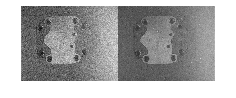

clear;
clc;

% Anzahl der Bilder
n = 100;

% img1 = imread('../Bilder/Bildrauschen1_1.png');

% Initialisierung des accumulators mit Nullen
acc1 = zeros(464,599);
acc1 = uint16(acc1);

acc2 = zeros(464,599);
acc2 = uint16(acc2);
% Iteration über beide Bildersätze
for i = 1:n
    % Einlesen des ersten Bildersatzes
    img1 = imread(sprintf('../Bilder/Bildrauschen1_%d.png',i));
    % Konvertieren in uint16
    img1 = uint16(img1);
    % Hinzufügen zum accumulator
    acc1 = imadd(img1,acc1);
    %2的点状噪音更多
    % Einlesen des zweiten Bildersatzes
    img2 = imread(sprintf('../Bilder/Bildrauschen2_%d.png',i));
    % Konvertieren in uint16
    img2 = uint16(img2);
    % Hinzufügen zum accumulator
    acc2 = imadd(img2,acc2);
end

% Dividieren durch die Anzahl der Bilder, um das Mittel zu berechnen
avg1 = acc1 / n;
avg2 = acc2 / n;

% Konvertieren des accumulators in 8-Bit-Darstellung
avg1 = uint8(avg1);
avg2 = uint8(avg2);
% Anzeigen des Ergebnisbildes
imshowpair(avg1,avg2,'montage');

- Unter welchen Bedingungen führt die Rauschunterdrückung durch Mittelung zum Erfolg? Diskutieren Sie, welche Vor- und Nachteile dieses Verfahren in der Praxis haben könnte!

*Die Rauschunterdrückung durch Mittelung kann erfolgreich sein, wenn die Bilder, die gemittelt werden, unabhängige Rauschquellen aufweisen. In diesem Fall werden die Rauschspitzen durch die Mittelung ausgeglichen und das Rauschen in den gemittelten Bildern wird reduziert. 如果被平均化的图像具有独立的噪声源，那么通过平均化来降低噪声是成功的。在这种情况下，噪声峰值被平均化补偿，平均化的图像中的噪声被降低。这种方法的一个优点是，它的实施简单而迅速。它在减少泊松噪声方面也很有效，这在数字图像捕捉中经常发生。然而，这种技术的一个缺点是，它在减少系统噪声方面不是很有效，因为它系统地存在于所有图像中。此外，由于信息在平均化过程中丢失，它可能会导致图像的清晰度和细节的减少。*

*Ein Vorteil dieses Verfahrens ist, dass es einfach und schnell zu implementieren ist. Es ist auch effektiv bei der Reduzierung von Poisson-Rauschen, das oft in digitalen Bildaufnahmen auftritt.*

*Ein Nachteil dieses Verfahrens ist jedoch, dass es nicht sehr effektiv bei der Reduzierung von Systemrauschen ist, da es systematisch über alle Bilder hinweg präsent ist. Darüber hinaus kann es zu einer Verminderung der Schärfe und Details im Bild führen, da bei der Mittelung Informationen verloren gehen.*

# *In der Praxis kann es auch schwierig sein, genug unabhängige Bilder zu erhalten, um eine ausreichende Mittelung durchzuführen. In solchen Fällen kann eine andere Methode der Rauschunterdrückung, wie z.B. die Verwendung eines bildbasierten Filters, zu besseren Ergebnissen führen.*

**2.    Rauschunterdrückung durch lokale Operatoren**

Sie haben drei einzelne Aufnahmen des Pumpengehäuses, die mit jeweils unterschiedlichen Arten von Rauschen behaftet sind (*Bild1, Bild2, Bild3*). Diese sollen nun mit Hilfe von Mittelwert-, Gauß- und Medianfilter verbessert werden.

- Welche Arten von Rauschen können Sie auf den drei Bildern erkennen? Diskutieren Sie, welche Filter für welches Rauschen am besten geeignet sein könnten!

- Überprüfen Sie Ihre Vermutungen nun experimentell. Lesen Sie im Script die einzelnen Bilder ein und wenden Sie die verfügbaren Filter darauf an. Benutzen Sie für Mittelwertfilter `fspecial`, für den Gaußfilter `imgaussfilt `und für den Medianfilter die Funktion `medfilt2`. 

- Stehen nur einzelne Aufnahmen zur Verfügung, so muss eine andere Methode angewendet werden. Das können beispielsweise lokale Operatoren sein. Im Wesentlichen werden drei verschiedene Operatoren angewendet: Mittelwertfilter, Gaußfilter und Medianfilter. Während die ersten beiden Faltungsoperatoren sind (siehe Faltungsmasken), ist letzterer ein morphologischer Operator. Während Ausreißer, wie sie z.B. beim Salt-and-Pepper Rauschen auftreten, trotz Mittelwert- und/oder Gaußfilter einen recht starken Einfluss haben, können sie vom Medianfilter in der Regel vollständig eliminiert werden. 如果只有个别图片，则必须使用另一种方法，局部操作符。基本上，使用了三种不同的运算符。平均值过滤器、高斯过滤器和中值过滤器。前两个是卷积运算符（见卷积掩码），而后者是一个形态学运算符。尽管平均数和/或高斯滤波器对异常值，如发生在盐和胡椒噪声中的异常值有相当大的影响，但通常可以通过中值滤波器完全消除。

Mittelwertfilter**均值滤波:** Dieser Filter berechnet den Durchschnittswert aller Pixel in einem bestimmten Bereich und setzt diesen Wert für das Zentralpixel. Dies kann helfen, Rauschen im Bild zu reduzieren, aber es kann auch zu Glättung von Kanten führen, da alle Pixel im Bereich gleich gewichtet werden. 这个过滤器计算一定区域内所有像素的平均值，并为中心像素设置这个值。这可以帮助减少图像中的噪音，但它也可以使边缘变得平滑，因为该区域的所有像素都被加权平等。

- Lineare Filter

- Durch die Berechnung des Mittelwerts werden die Kanten- und Merkmalsinformationen im Bild "verwischt", und viele Merkmale gehen verloren.

- **imgaussfilt直接对图片进行高斯滤波，相关设置包括**`FilterSize` - 高斯滤波器的大小, `Padding` - 图像填充, `FilterDomain` - 要在其中执行滤波的域

- **imfilter编写高斯函数与图片相关运算滤波, fspecial生成高斯模板**

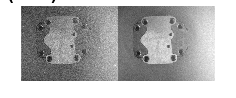

img1 = imread('../Bilder/Bild1.png');
Mittelwertfilter1 = imfilter(img1,fspecial("average"));
% Gaussfilter1 = imfilter(img1,fspecial("gaussian"));
Gaussfilter1 = imgaussfilt(img1,1); %标准差为 4
imshowpair(img1,Mittelwertfilter1,'montage');
title('Original Image (Left) Vs. Mittelwertfilter Image (Right)')

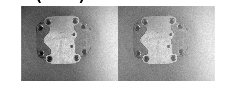

Medianfilter1 = medfilt2(img1);
imshowpair(Gaussfilter1,Medianfilter1,'montage');
title('Gaussfilter (Left) Vs. Medianfilter (Right)')

高斯滤波 Gaussfilter: Der Gaussfilter nutzt eine Gaussfunktion, um Pixel in einem Bereich zu gewichten. Pixel in der Nähe des Zentralpixel werden höher gewichtet als Pixel, die weiter entfernt sind. Daher ist der Gaussfilter in der Regel besser in der Lage, tatsächliche Kanten zu erhalten, als der Mittelwertfilter, aber es ist auch langsamer in der Berechnung. 高斯滤波器使用一个高斯函数对一个区域的像素进行加权。靠近中心像素的像素的权重高于较远的像素。因此，高斯滤波器通常比均值滤波器更能保留实际的边缘，但它的计算速度也比较慢。

- Lineare Filter

- Verändert nicht die Kantenausrichtung des Originalbildes

- Garantierte Punkt- und Kanteneigenschaften.

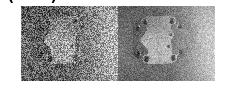

img2 = imread('../Bilder/Bild2.png');
Mittelwertfilter2 = imfilter(img2,fspecial("average"));
Gaussfilter2 = imgaussfilt(img2,2); %标准差为 4
imshowpair(img2,Mittelwertfilter2,'montage');
title('Original Image (Left) Vs. Mittelwertfilter Image (Right)')

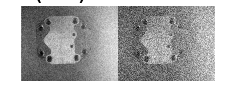

Medianfilter2 = medfilt2(img2);
imshowpair(Gaussfilter2,Medianfilter2,'montage');
title('Gaussfilter (Left) Vs. Medianfilter (Right)')

**中位数滤波是图像处理中一种常用的非线性运算, 用于减少“椒盐”噪声。当目标是同时减少噪声和保持边缘时，中位数滤波比卷积更高效。** Gaussfilter: Der Gaussfilter nutzt eine Gaussfunktion, um Pixel in einem Bereich zu gewichten. Pixel in der Nähe des Zentralpixel werden höher gewichtet als Pixel, die weiter entfernt sind. Daher ist der Gaussfilter in der Regel besser in der Lage, tatsächliche Kanten zu erhalten, als der Mittelwertfilter, aber es ist auch langsamer in der Berechnung.

- Nichtlineare Filterung

- Hervorragend im Umgang mit Impulsrauschen und Pfefferrauschen und wirksam im Schutz der Kanteninformationen des Bildes.

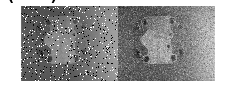

img3 = imread('../Bilder/Bild3.png');
Mittelwertfilter3 = imfilter(img3,fspecial("average"));
Gaussfilter3 = imgaussfilt(img3,1); %标准差为 4
imshowpair(img3,Mittelwertfilter3,'montage');
title('Original Image (Left) Vs. Mittelwertfilter Image (Right)')

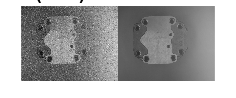

Medianfilter3 = medfilt2(img3);
imshowpair(Gaussfilter3,Medianfilter3,'montage');
title('Gaussfilter (Left) Vs. Medianfilter (Right)')

- Beurteilen Sie nach Ihrem subjektiven Empfinden die Ergebnisbilder. Inwieweit wurden Ihre Vermutungen bestätigt oder widerlegt? Inwiefern unterscheiden sich die verschiedenen Filter bzgl. der Erhaltung von tatsächlichen Kanten im Bild?

**3.    Rauschunterdrückung im Frequenzbereich**

Die Rauschunterdrückung soll nun nicht mehr über lokale Operatoren, sondern global im Frequenzbereich durchgeführt werden. Grundsätzlich entspricht eine Faltung einer Multiplikation im Frequenzbereich, sodass wir die lokalen Operatoren aus Aufgabe 2 (Kernels) zu Masken im Frequenzbereich umwandeln können und auf das Amplitudenbild anwenden können. Zusätzlich dazu können wir aber auch andere Operationen im Frequenzbereich durchführen. Dazu gehören u.a. **der Hochpass zur Kantendetektion und der Tiefpass zur Rauschunterdrückung. **现在，降噪不再是通过局部运算器进行，而是在频域中全局进行。基本上，卷积相当于频域中的乘法，因此我们可以将任务2中的局部算子（核）转换为频域中的掩码，并将其应用于振幅图像。除此以外，我们还可以在频域中进行其他操作。这些包括用于边缘检测的高通和用于降噪的低通。

- Entwickeln Sie ein Script, das ein Bild, z.B.*"verschmutztes_Werkstuek_FhG_IPK.jpg"*, einliest, in den Fourierbereich transformiert und auch wieder zurück. Lassen Sie sich alle Zwischenergebnisse anzeigen und probieren Sie verschiedene Bilder aus, um das Amplitudenbild interpretieren zu können. Verwenden Sie für die Transformation `fft2` bzw. `ifft2`. Um das Amplitudenbild sichtbar zu machen, eignet sich `imshow(log(abs(FFTImage) + 1), [])`. 

- Um die niedrigen Frequenzanteile in der Bildmitte statt in den Außenbereichen anzuzeigen, verwenden Sie im Script `fftshift.`

- Fügen Sie nun die eigentliche Operation (Hoch-/Tiefpass) im Frequenzbereich ein, indem Sie das Frequenzbild mit einer Filtermaske multiplizieren. Zum Erstellen der Filtermaske verwenden Sie die vorbereitete Funktion `createFFTMask(imageSizeX, imageSizeY, radius, "highpass/lowpass")`. Anschließend müssen die niedrigen Frequenzanteile mit `ifftshift` wieder aus dem Bildzentrum in die Bildecken verschoben werden und das Bild mit `ifft2` zurücktransformiert werden. Lassen Sie sich die Amplitudenbilder vor und nach der Multiplikation anzeigen, um die Operation besser nachvollziehen zu können.

- Wenden Sie Ihr Skript für Hoch- und Tiefpass auch auf die Testbilder *blackTriangle, whiteblock, whiteCircle *an. Sie werden Filterungs-Artefakte beobachten (sog. „Ringing“). Recherchieren Sie, warum diese Artefakte entstehen und welche Möglichkeiten es gibt um deren Entstehung zu verhindern!

Bild einlesen und in *grayscale* konvertieren:

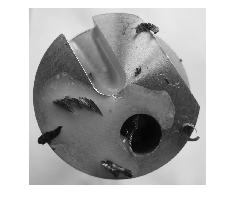

 % Bild einlesen
img = imread('../Bilder/verschmutztes_Werkstuek_FhG_IPK.jpg');
% Konvertieren in Graustufen
img = im2gray(img);
imshow(img)

Fouriertransformation:

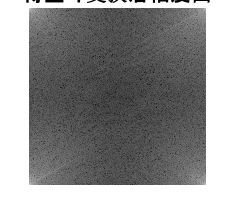

% Transformieren in den Frequenzbereich
FFTImage  = fft2(img);
imshow(log(abs(FFTImage) + 1), [])
title('傅里叶变换后幅度图');

niedrige Frequenzanteile in die Bildmitte:

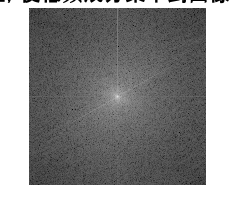

% 移位，使低频成分集中到图像中心，并得到幅度谱
FFTImage = fftshift(FFTImage);
% % 平移回来
% img_ifftshift = ifftshift(img_fftshift);
% % 傅里叶反变换
% % Inverse Fourier-Transformation
% img_ifft = ifft2(img_ifftshift);
% % imshowpair(amplitude_spectrum,abs(img_ifft),'montage');
imshow(log(abs(FFTImage)), []);
title('移位，使低频成分集中到图像中心');

Filtermaske erstellen und mit transformiertem Bild multiplizieren (mit .*  Array multiply):

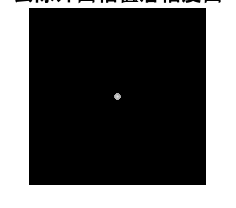

% Anwenden der Filtermaske 对幅度图进行操作，去除外围的高频成分的幅度值，也就是将高频成分能量去除了
mask = createFFTMask(size(img, 1), size(img, 2), 15, 'lowpass');
FFTImage = FFTImage .* mask;
imshow(log(1+abs(FFTImage)), []);
title('去除外围幅值后幅度图');

niedrige Frequenzanteile mit `ifftshift` wieder aus dem Bildzentrum in die Bildecken:

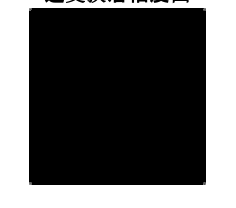

IFFTImage  = ifftshift(FFTImage);
% Anzeigen des gefilterten Bildes
imshow(log(abs(IFFTImage)), []);
title('逆变换后幅度图');

inverse Fouriertransformation und gefiltertes Bild anzeigen:

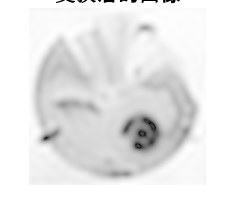

% Transformieren zurück in den Ortsbereich
filteredImage = ifft2(IFFTImage);
% i = im2uint8(mat2gray(abs(img_filtered)));
% filteredImage = uint8(real(filteredImage));
% imshow(filteredImage);
imshow(log(abs(filteredImage) + 1), []);
title('变换后的图像');

Test

% img1 = imread('../Bilder/blackTriangle.png');
% img2 = imread('../Bilder/whiteblock.png');
% img3 = imread('../Bilder/whiteCircle.png');
% mask = createFFTMask(size(img1, 1), size(img2, 2), 100, 'highpass');
% FFTImage = FFTImage .* mask;

"Ringing"-Artefakte entstehen, weil bei der Anwendung von Filtern im Frequenzbereich manchmal hochfrequente Anteile verstärkt oder unterdrückt werden, die nicht vollständig entfernt werden können. Dies führt zu einer Übersteuerung und Unterdrückung bestimmter Frequenzen und zu einer Verzerrung des Ausgangsbildes.

Eine Möglichkeit, um dessen Entstehung zu verhindern, ist die Verwendung von gebrochenen (Windowed) Filtern, die den Übergang zwischen dem Filterbereich und dem Nicht-Filterbereich glätten. Eine weitere Möglichkeit ist die Verwendung von konjugiert-symmetrischen Filtern, die eine bessere Stabilität im Frequenzbereich gewährleisten.

出现 "振铃 "伪影是因为当滤波器应用于频域时，高频成分有时会被放大或抑制，无法完全去除。这导致了对某些频率的过度调制和抑制，并导致输出图像的失真。

防止这种情况发生的一种方法是使用破碎（窗口）滤波器，使过滤和非过滤区域之间的过渡变得平滑。另一种可能是使用共轭对称滤波器，它在频域中提供更好的稳定性。

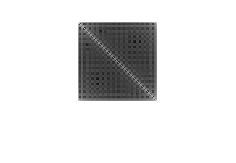

% Lesen Sie das Bild ein
img = imread('../Bilder/blackTriangle.png');
% whiteblock,whiteCircle,blackTriangle

% Konvertieren Sie das Bild in den Graustufenbereich
% img = rgb2gray(img);
img = im2gray(img);

% Führen Sie die Fourier-Transformierung durch
FFTImage = fft2(img);
imshow(log(abs(FFTImage)), []);

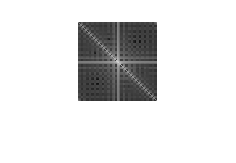


% Verschieben Sie die niedrigen Frequenzanteile in die Bildmitte
FFTImage = fftshift(FFTImage);
imshow(log(abs(FFTImage)), []);


% Erstellen Sie eine Filtermaske (z.B. Hochpass)
mask = createFFTMask(size(img, 1), size(img, 2), 100, "lowpass");

% Anwenden der Filtermaske auf das Frequenzbild
FFTImage = FFTImage .* mask;

% Verschieben Sie die niedrigen Frequenzanteile wieder zurück in die Bildecke
FFTImage = ifftshift(FFTImage);
imshow(log(abs(FFTImage)), []);

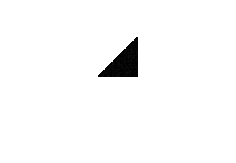


% Führen Sie die Inverse Fourier-Transformierung durch
filteredImage = ifft2(FFTImage);
imshow(log(abs(filteredImage)), []);

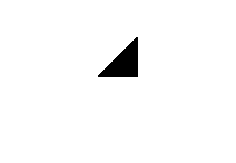


% Wandeln Sie das Ergebnis in den uint8-Datentyp um
filteredImage = uint8(real(filteredImage));

% Zeigen Sie das Ergebnisbild an
imshow(filteredImage);